# Inverse Kinematics of 2-D Planar Robot using Robotic System Toolbox

## Construct The Robot

Create a `rigidBodyTree` object and rigid bodies with their associated joints. Specify the geometric properties of each rigid body and add it to the robot.

Start with a blank rigid body tree model.

clear;
robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

Specify arm lengths for the robot arm.

L1 = 1;
L2 = 1;
desired = [0.5 0.5 0];

Add `'link1'` body with `'joint1'` joint.

body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,trvec2tform([0 0 0]))
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'base');

Add `'link2'` body with `'joint2'` joint.

body = rigidBody('link2');
joint = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint, trvec2tform([L1,0,0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link1');

Add `'tool'` end effector with `'fix1'` fixed joint.

body = rigidBody('tool');
joint = rigidBodyJoint('fix1','fixed');
setFixedTransform(joint, trvec2tform([L2, 0, 0]));
body.Joint = joint;
addBody(robot, body, 'link2');

Show details of the robot to validate the input properties. The robot should have two non-fixed joints for the rigid bodies and a fixed body for the end-effector.

showdetails(robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   tool(3)  
   3         tool          fix1         fixed            link2(2)   
--------------------


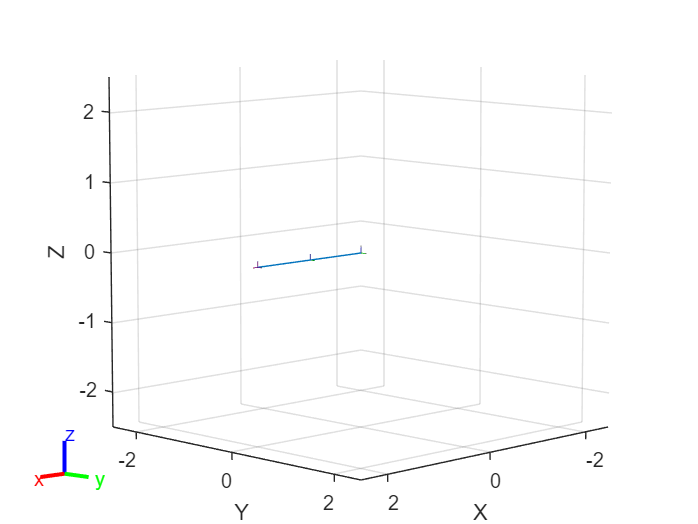

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

show(robot)

## Inverse Kinematics Solution

Use an `inverseKinematics` object to find a solution of robotic configurations that achieve the given end-effector positions along the trajectory. 

Pre-allocate configuration solutions as a matrix `qs`.

q0 = homeConfiguration(robot);

Create the inverse kinematics solver. Because the *xy* Cartesian points are the only important factors of the end-effector pose for this workflow, specify a non-zero weight for the fourth and fifth elements of the  `weight` vector. All other elements are set to zero.

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
endEffector = 'tool';

Loop through the trajectory of points to trace the circle. Call the `ik` object for each point to generate the joint configuration that achieves the end-effector position. Store the configurations to use later.

[qSol, qInfo] = ik(endEffector,trvec2tform(desired),weights,q0)

qSol =    -0.4240
    2.4189


qInfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 2
        PoseErrorNorm: 7.2131e-09
             ExitFlag: 1
               Status: 'success'

## The Solution

Plot the robot for each frame of the solution using that specific robot configuration. Also, plot the desired trajectory.

Show the robot in the first configuration of the trajectory. Adjust the plot to show the 2-D plane that circle is drawn on. Plot the desired trajectory.

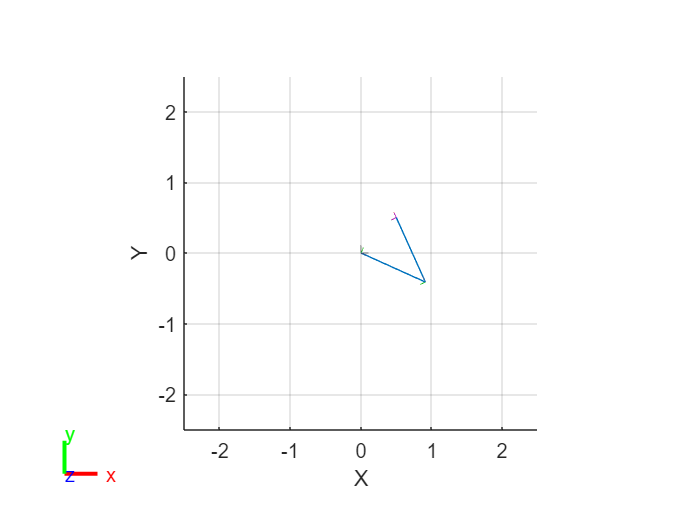

figure
show(robot,qSol);
view(2)
ax = gca;
ax.Projection = 'orthographic';

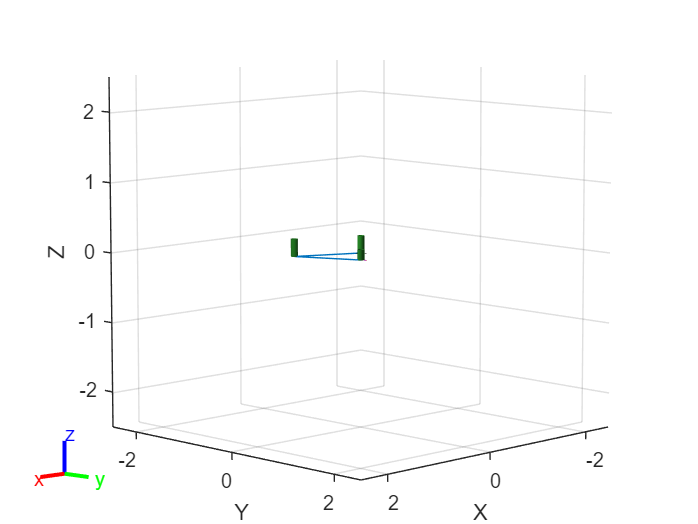

collisionL1 = collisionCylinder(0.05,0.25);
collisionL1.Pose = trvec2tform([0 0 0.25/2]);
collisionL2 = collisionCylinder(0.05,0.25);
collisionL2.Pose = trvec2tform([0 0 0.25/2]);
collisionEF = collisionCylinder(0.05,0.15);
collisionEF.Pose = trvec2tform([0 0 0.15/2]);

addCollision(robot.Bodies{1},collisionL1)
addCollision(robot.Bodies{2},collisionL2)
addCollision(robot.Bodies{3},collisionEF)
show(robot,qSol, 'Collisions','on','Visuals','off');